## 求和——sum

sum=(1/1+1/2+...1/n)

sum(1./(1:100))

ans = 5.1874

## **求积——prod**

**prod(1:n)=n!**

prod(1:100)

ans = 9.3326e+157

## **极限——limit( f(x), x, 趋向的数, 左/右极限 )**

**x为变量**

Right limit (x→a + 0):

limit(f(x), x, a, 'right')

函数或变量 'f' 无法识别。

Left limit (x→a − 0): 

limit(f(x), x, a, 'left')

Limit to indefinite large (x→ + ∞): 

limit(f(x), x, +inf)

Limit to indefinite small (x→ − ∞): 

limit(f(x), x, -inf)

例1：

syms n
limit((2*n^3+1)/(5*n^3+1),n,inf)

$$ans = \frac{2}{5}$$

例2：

#### ezplot('f(x)',[x1,x2])--非隐函数用法

f(x)为字符类型

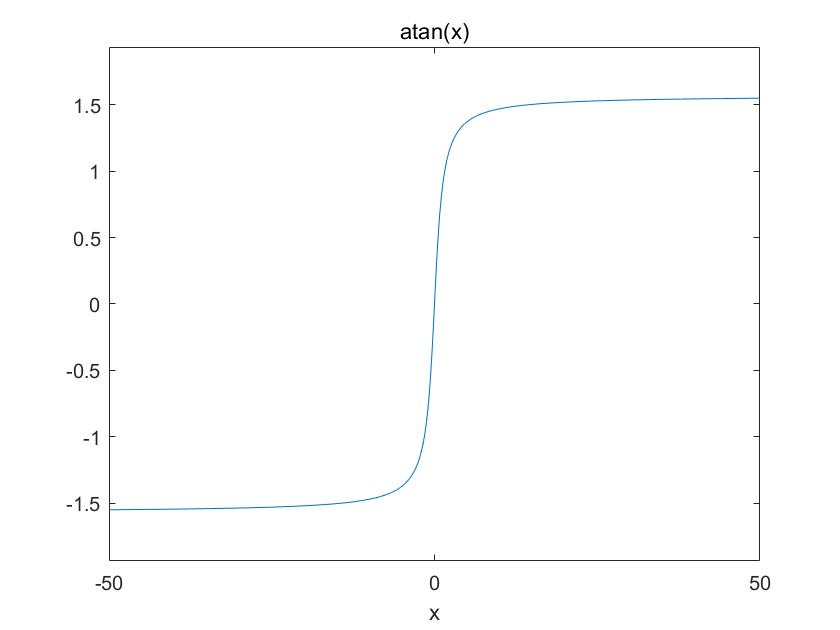

ezplot('atan(x)',[-50,50])

syms x
limit(atan(x), x, +inf)

$$ans = \frac{\pi }{2}$$

limit(atan(x), x, -inf)

$$ans = -\frac{\pi }{2}$$

例3：

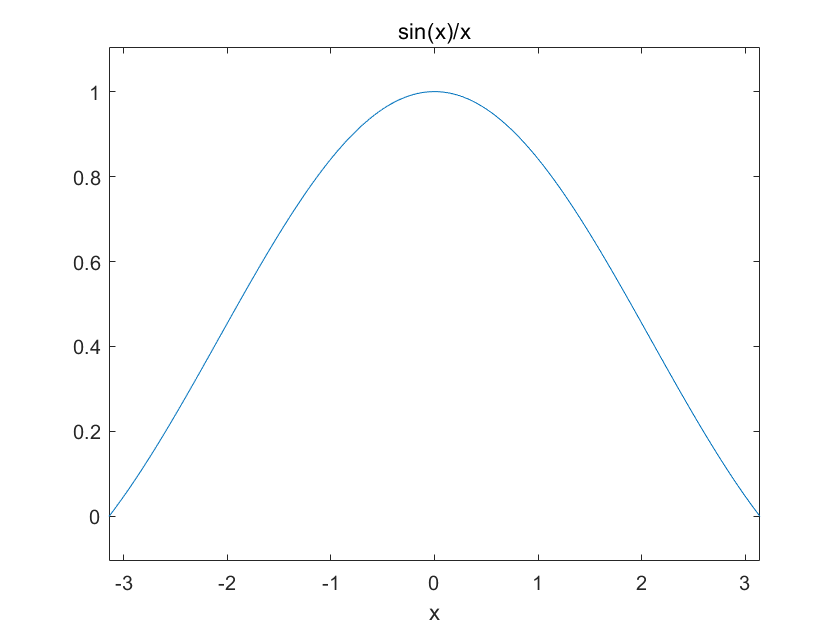

ezplot('sin(x)/x',[-pi,pi])

syms x
limit(sin(x)/x, x, 0)

$$ans = 1$$

例4：

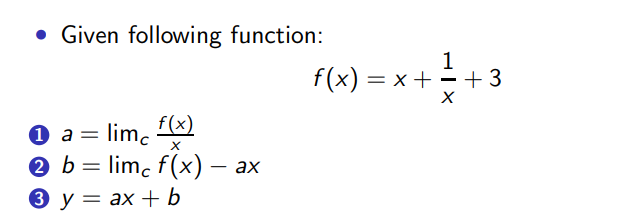

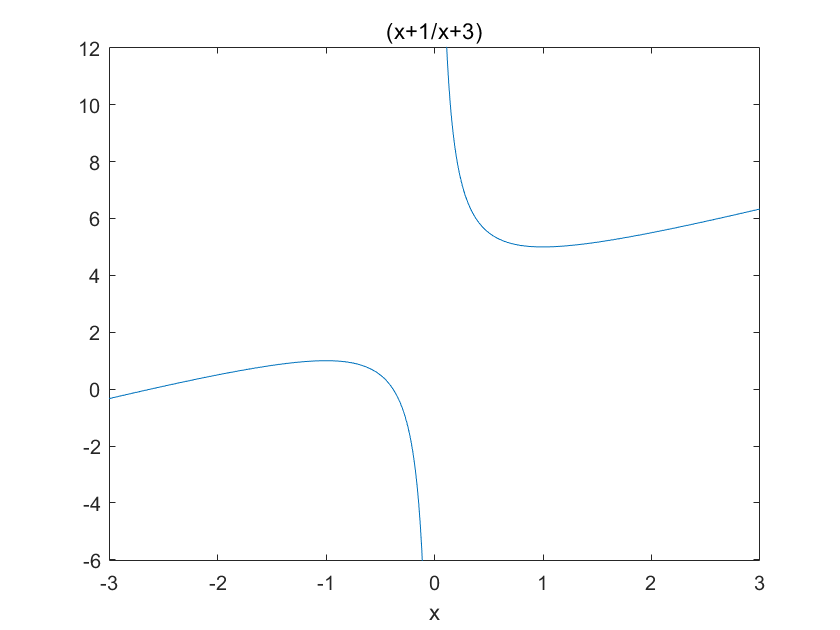

ezplot('(x+1/x+3)',[-3,3])

clear; syms x;
a=limit((x+1/x+3)/x, x, inf)

$$a = 1$$

b=limit((x+1/x+3)-a*x,x,inf)

$$b = 3$$

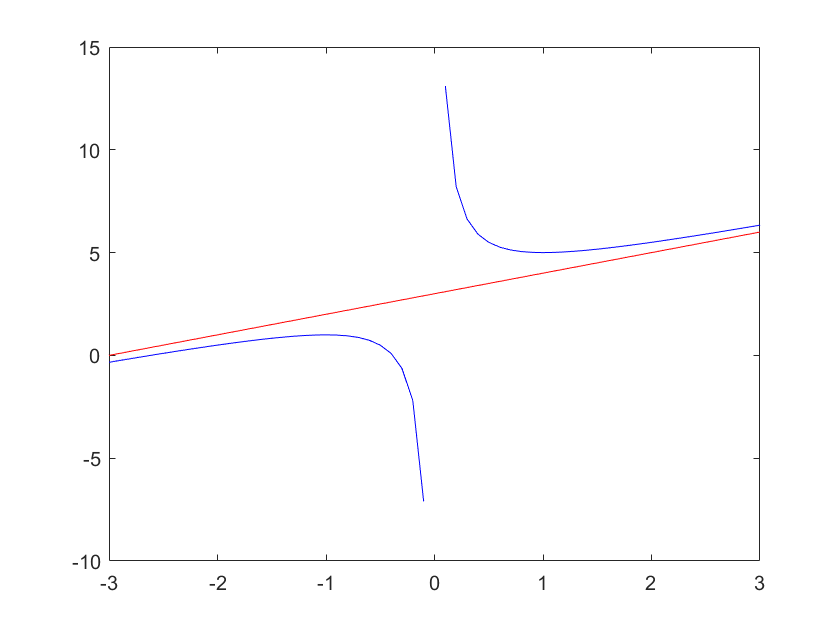

x=-3:0.1:3;
f=x+1./x+3;
y=a*x+b;
plot(x,f,'b',x,y,'r')

## 导数——diff(f(x), 次数)

syms x
diff(x^3-3*x^2+x+1)

$$ans = 3\,x^{2}-6\,x+1$$

x=-1:0.1:3

x =    -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000


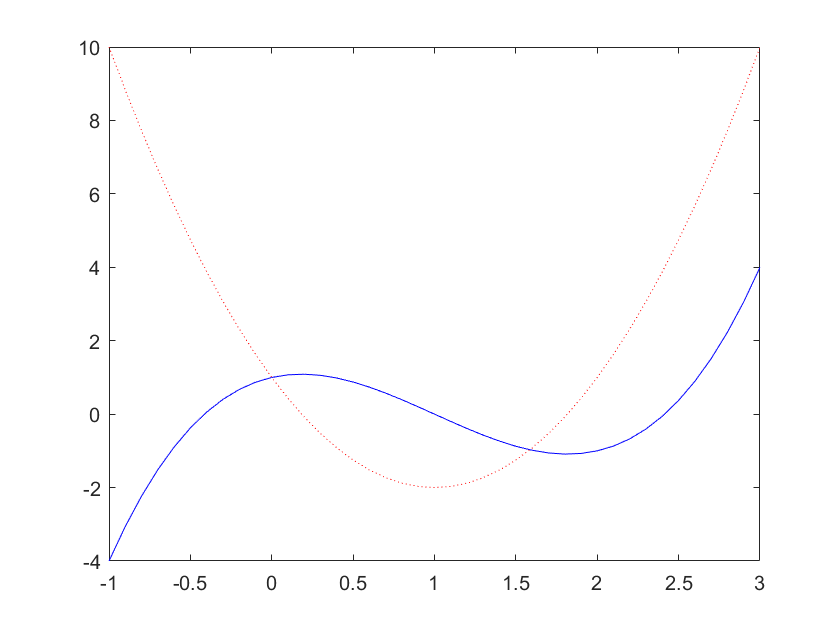

y1=x.^3-3*x.^2+x+1;%原函数
y2=3*x.^2-6*x+1;%导数
plot(x, y1,'b',x,y2,'r:')

### 隐函数求导

结论：

 另，当分母dx趋于0时，要用limit逼近求值

例1：

syms t
f=diff(exp(t)*cos(t))

$$f = {\mathrm{e}}^{t}\,\cos\left(t\right)-{\mathrm{e}}^{t}\,\sin\left(t\right)$$

g=diff(exp(t)*sin(t))

$$g = {\mathrm{e}}^{t}\,\cos\left(t\right)+{\mathrm{e}}^{t}\,\sin\left(t\right)$$

ans=g/f

$$ans = \frac{{\mathrm{e}}^{t}\,\cos\left(t\right)+{\mathrm{e}}^{t}\,\sin\left(t\right)}{{\mathrm{e}}^{t}\,\cos\left(t\right)-{\mathrm{e}}^{t}\,\sin\left(t\right)}$$

### 求切线

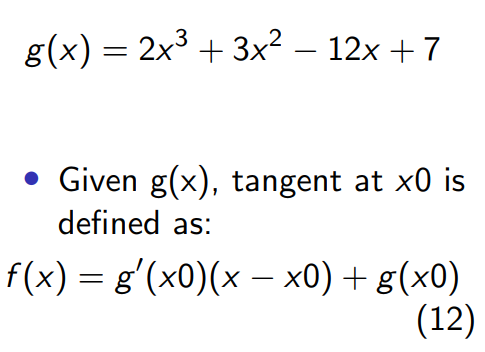

求x=-1时，与曲线g相切的直线

syms x
f = 2*x^3+3*x^2-12*x+7;
df = diff(f)

$$df = 6\,x^{2}+6\,x-12$$


x = -1;%
f0 = eval(f)

f0 = 20

df0 = eval(df)

df0 = -12


x = -4:0.1:3

x =    -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000


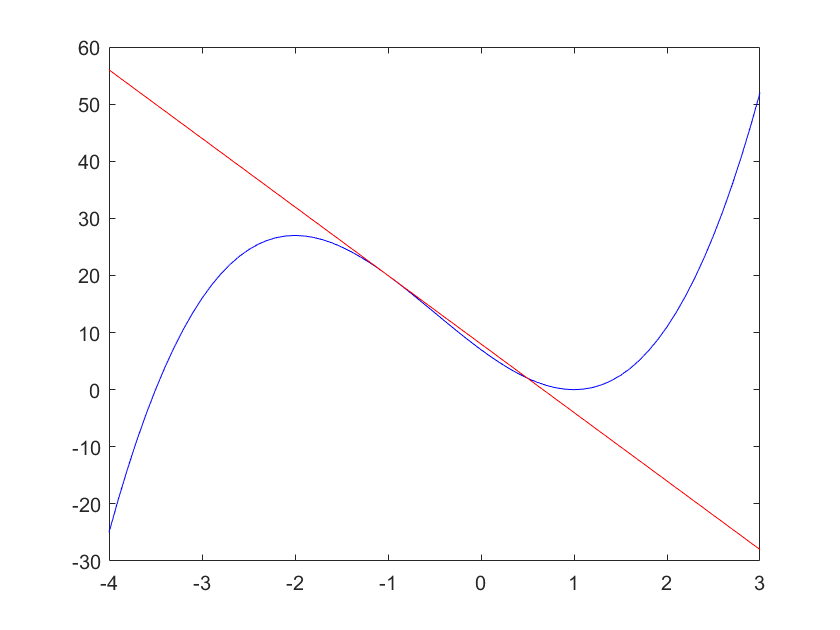

h1 = 2.*x.^3+3.*x.^2-12.*x+7;
h2 = df0.*(x-(-1))+f0;
plot(x, h1, 'b', x, h2, 'r')